InitBreach;
clc;
clear S;
close all;

Specify Video File

videoFileName = '05_highway_lanechange_25s.mp4';

x0_host = 0;
v0_host = 20;
vref_host = 20;
Ts = 0.05;
endTime = 500;
dSafe = 2;

% The file TrackLeadVehicle modifies the code taken from Matlab reference
% example to calculate the all lead car positions and saves that in a
% matlab file. This script loads from the saved file and calculates the
% lead car position at each time step (i.e., in each frame of video).

% Setup Video Reader and Player
% videoReader = VideoReader(videoFileName);
% videoPlayer = vision.DeployableVideoPlayer();

%%%%% MODIFY THIS %%%%%%%
lead_car_pos = 20*ones(endTime, 1);
a = load('AllLeadVehicles.mat', 'leadVehicles');
for i = 1:numel(lead_car_pos)
    c_lead_pos = 20;
    currentLeadVehicles = a.leadVehicles{i};
    minY = 100.0;
    for j = 1:numel(currentLeadVehicles)
        lv = currentLeadVehicles{j};
        if (lv(2) < minY)
            c_lead_pos = lv(1);
            minY = lv(2);
        end
    end
    lead_car_pos(i) = c_lead_pos;
end

S = BreachSimulinkSystem('ACC_HW3');

Found var Ts in base workspace used by ACC_HW3_breach.
Found var dSafe in base workspace used by ACC_HW3_breach/Adaptive Cruise Control System/Constant.
Found var v0_host in base workspace used by ACC_HW3_breach/Constant.
Found var vref_host in base workspace used by ACC_HW3_breach/Host Car/Saturation.
Found var x0_host in base workspace used by ACC_HW3_breach/Constant1.


tspan = 0:Ts:endTime;
S.SetTime(tspan);
inputGen.type = 'UniStep';
inputGen.cp = endTime;
S.SetInputGen(inputGen);
params = cell(1,endTime);
for jj=1:endTime
    params{1,jj} = sprintf('dist_u%d',jj-1);
end

S.PrintParams;

-- PARAMETERS --
Ts=0.05       
dSafe=2       
v0_host=20       
vref_host=20       
x0_host=0       
dist_u0=0       
dist_u1=0       
dist_u2=0       
dist_u3=0       
dist_u4=0       
dist_u5=0       
dist_u6=0       
dist_u7=0       
dist_u8=0       
dist_u9=0       
dist_u10=0       
dist_u11=0       
dist_u12=0       
dist_u13=0       
dist_u14=0       
dist_u15=0       
dist_u16=0       
dist_u17=0       
dist_u18=0       
dist_u19=0       
dist_u20=0       
dist_u21=0       
dist_u22=0       
dist_u23=0       
dist_u24=0       
dist_u25=0       
dist_u26=0       
dist_u27=0       
dist_u28=0       
dist_u29=0       
dist_u30=0       
dist_u31=0       
dist_u32=0       
dist_u33=0       
dist_u34=0       
dist_u35=0       
dist_u36=0       
dist_u37=0       
dist_u38=0       
dist_u39=0       
dist_u40=0       
dist_u41=0       
dist_u42=0       
dist_u43=0       
dist_u44=0       
dist_u45=0       
dist_u46=0       
dist_u47=0       
dist_u48=0       
dist_u49=0       
dist_u50

S.SetParam(params, lead_car_pos(1:endTime));
S.PrintParams;

-- PARAMETERS --
Ts=0.05       
dSafe=2       
v0_host=20       
vref_host=20       
x0_host=0       
dist_u0=20       
dist_u1=20       
dist_u2=71.9647       
dist_u3=73.6097       
dist_u4=77.1477       
dist_u5=65.6759       
dist_u6=62.7855       
dist_u7=61.391       
dist_u8=64.816       
dist_u9=63.1711       
dist_u10=62.7417       
dist_u11=66.9421       
dist_u12=67.59       
dist_u13=68.2505       
dist_u14=68.924       
dist_u15=69.611       
dist_u16=37.3645       
dist_u17=36.4275       
dist_u18=35.6185       
dist_u19=34.9808       
dist_u20=36.2929       
dist_u21=37.3088       
dist_u22=38.0065       
dist_u23=38.4154       
dist_u24=36.5883       
dist_u25=37.1489       
dist_u26=71.9873       
dist_u27=71.9873       
dist_u28=71.9873       
dist_u29=71.972       
dist_u30=71.9629       
dist_u31=71.9575       
dist_u32=71.9542       
dist_u33=71.9525       
dist_u34=71.9629       
dist_u35=71.9618       
dist_u36=71.9732       
dist_u37=71.9747       
dist_u38=71.9

numSimulations = 1;
S.QuasiRandomSample(numSimulations);
S.Sim;

clc;

STL_ReadFile('./ACC_Requirements.stl');
disp('Checking safe following ..');

Checking safe following ..


robs1 = S.CheckSpec(safeFollowing);
disp(robs1);

   18.0000



disp('Checking forward progress');

Checking forward progress


robs2 = S.CheckSpec(forwardProgress);
disp(robs2);

   10.8480



disp('Checking if cruising works');

Checking if cruising works


robs3 = S.CheckSpec(cruiseWhenNotImpeded);
disp(robs3);

     2



disp('Checking that the host stops only if required');

Checking that the host stops only if required


robs4 = S.CheckSpec(dontStopUnlessLeadStops);
disp(robs4);

   19.9000



## Pretty-printing plots by getting signal values and grouping them

together. DO NOT USE this if numSimulations is a large number, because Matlab will open 'numSimulations' figure windows, and it could slow down your Matlab or even cause it to crash!

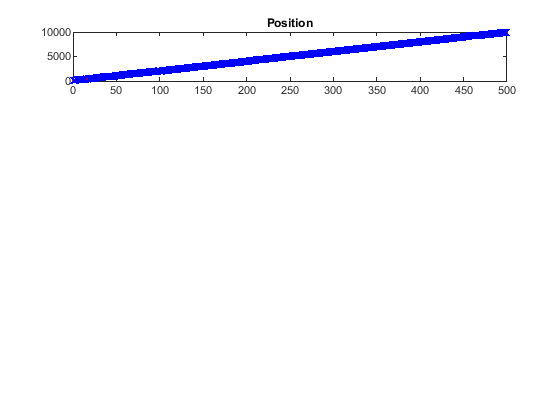

signalValues = S.GetSignalValues({'HostPosition','LeadPosition'});
close all;

% as a safeguard, you could use min(numSimulations,20) instead of
% numSimulations as the loop termination condition below:
figure;
trace = signalValues;
subplot(5,1,1);
plot(tspan,trace(1,:),'-r.', tspan, trace(2,:), '-bx');
title('Position');